load("DynamicConstants.mat")
figureWidth = 7; % cm (max. 15)
figureRatio = 1; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
RGB = rgb2hex(orderedcolors("gem"));

Tp_c_up = [Tp_c_1([1,3,5,7]) Tp_c_2([1,3,5,7]) Tp_c_3([1,3,5]) Tp_c_4([1,3,5])];
Tp_h_up = [Tp_h_1([1,3,5,7]) Tp_h_2([1,3,5,7]) Tp_h_3([1,3,5]) Tp_h_4([1,3,5])];
Tp_c_down = [Tp_c_1([2 4 6 8]) Tp_c_2([2 4 6 8]) Tp_c_3([2 4 6]) Tp_c_4([2 4 6])];
Tp_h_down = [Tp_h_1([2 4 6 8]) Tp_h_2([2 4 6 8]) Tp_h_3([2 4 6]) Tp_h_4([2 4 6])];

Tp_all_up = [Tp_c_1([1,3,5,7]) Tp_c_2([1,3,5,7]) Tp_c_3([1,3,5]) Tp_c_4([1,3,5]) Tp_h_1([1,3,5,7]) Tp_h_2([1,3,5,7]) Tp_h_3([1,3,5]) Tp_h_4([1,3,5])];
Tp_all_down = [Tp_c_1([2 4 6 8]) Tp_c_2([2 4 6 8]) Tp_c_3([2 4 6]) Tp_c_4([2 4 6]) Tp_h_1([2 4 6 8]) Tp_h_2([2 4 6 8]) Tp_h_3([2 4 6]) Tp_h_4([2 4 6])];

Tp_small = [Tp_c_1 Tp_c_2 Tp_h_1 Tp_h_2]

Tp_small =     0.0292    0.0474    0.0299    0.0296    0.0304    0.0253    0.0323    0.0329    0.0282    0.0458    0.0277    0.0265    0.0256    0.0235    0.0269    0.0268    0.0352    0.0439    0.0380    0.0292    0.0390    0.0252    0.0293    0.0280    0.0360    0.0572    0.0401    0.0294    0.0322    0.0267    0.0226    0.0355


Tp_large = [Tp_c_3 Tp_c_4 Tp_h_3 Tp_h_4]

Tp_large =     0.0296    0.0368    0.0324    0.0344    0.0243    0.0320    0.0403    0.0392    0.0367    0.0379    0.0279    0.0349    0.0347    0.0360    0.0418    0.0338    0.0295    0.0320    0.0438    0.0370    0.0417    0.0313    0.0310    0.0369



Tp_all = [Tp_all_up Tp_all_down]

Tp_all =     0.0292    0.0299    0.0304    0.0323    0.0282    0.0277    0.0256    0.0269    0.0296    0.0324    0.0243    0.0403    0.0367    0.0279    0.0352    0.0380    0.0390    0.0293    0.0360    0.0401    0.0322    0.0226    0.0347    0.0418    0.0295    0.0438    0.0417    0.0310    0.0474    0.0296    0.0253    0.0329    0.0458    0.0265    0.0235    0.0268    0.0368    0.0344    0.0320    0.0392    0.0379    0.0349    0.0439    0.0292    0.0252    0.0280    0.0572    0.0294    0.0267    0.0355


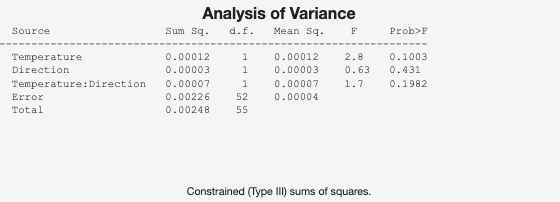


% Then continue with the ANOVA code
y = [Tp_c_up, Tp_h_up, Tp_c_down, Tp_h_down];

n = length(Tp_c_up);

temperature = [ones(n,1); 2*ones(n,1); ones(n,1); 2*ones(n,1)];
direction = [ones(n,1); ones(n,1); 2*ones(n,1); 2*ones(n,1)];

[p, tbl, stats] = anovan(y, {temperature, direction}, ...
    'model', 'interaction', ...
    'varnames', {'Temperature', 'Direction'});


disp(tbl);

    {'Source'               }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'  }
    {'Temperature'          }    {[1.2176e-04]}    {[   1]}    {[        0]}    {[1.2176e-04]}    {[  2.7996]}    {[  0.1003]}
    {'Direction'            }    {[2.7396e-05]}    {[   1]}    {[        0]}    {[2.7396e-05]}    {[  0.6299]}    {[  0.4310]}
    {'Temperature:Direction'}    {[7.3868e-05]}    {[   1]}    {[        0]}    {[7.3868e-05]}    {[  1.6984]}    {[  0.1982]}
    {'Error'                }    {[    0.0023]}    {[  52]}    {[        0]}    {[4.3493e-05]}    {0×0 double}    {0×0 double}
    {'Total'                }    {[    0.0025]}    {[  55]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double}



p

p =     0.1003
    0.4310
    0.1982


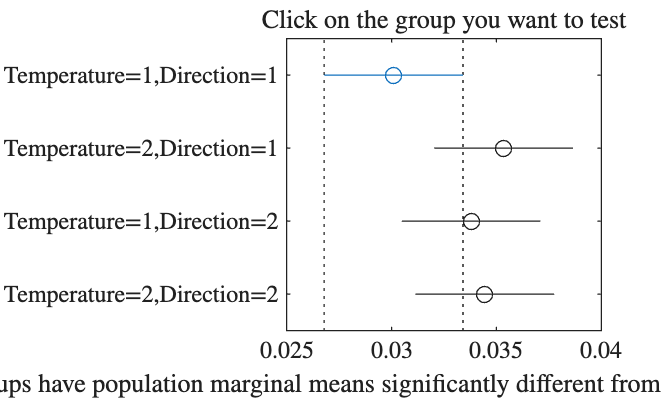


% If interaction is significant, run post-hoc comparisons
multcompare(stats, 'Dimension', [1 2]);

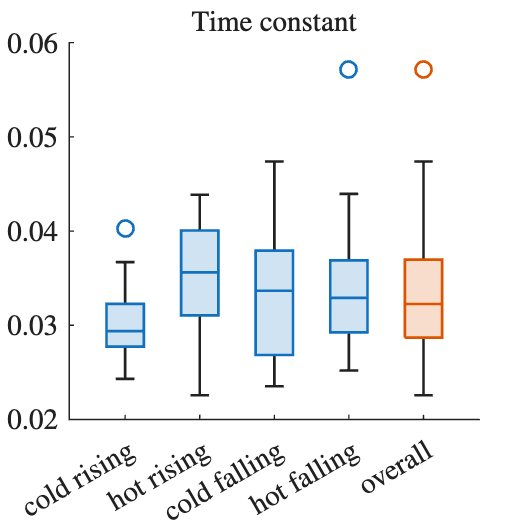


figure, clf, hold on
boxchart([Tp_c_up',Tp_h_up',Tp_c_down',Tp_h_down'])
boxchart([NaN(length([Tp_all_up Tp_all_down]),1) NaN(length([Tp_all_up Tp_all_down]),1) NaN(length([Tp_all_up Tp_all_down]),1) NaN(length([Tp_all_up Tp_all_down]),1) [Tp_all_up Tp_all_down]'])
Tp_sorted = sort([Tp_all_up Tp_all_down],"descend");
% yline(Tp_sorted(2), '--', 'Label',round(Tp_sorted(2), 3),'LabelHorizontalAlignment','right')
% yline(Tp_sorted(end), '--', 'Label',round(Tp_sorted(end),3),'LabelHorizontalAlignment','right')
xticklabels({'cold rising', 'hot rising','cold falling','hot falling', 'overall'})
title('Time constant')
set(findall(gca, 'Type', 'Line'), 'LineWidth', 1.5);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

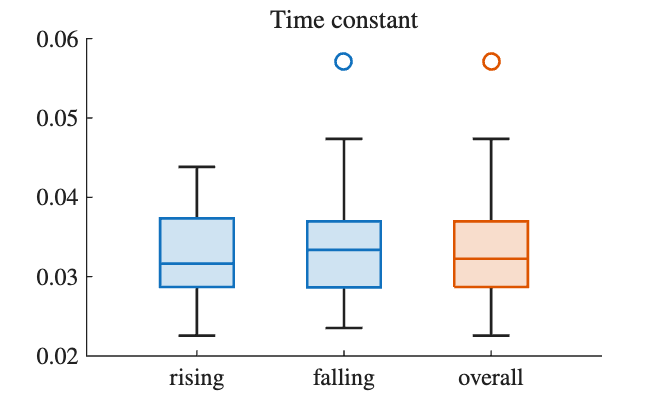


figure, clf, hold on
boxchart([[Tp_c_up Tp_h_up]', [Tp_c_down Tp_h_down]'])
boxchart([NaN(length([Tp_all_up Tp_all_down]),1) NaN(length([Tp_all_up Tp_all_down]),1) [Tp_all_up Tp_all_down]'])
xticklabels({'rising','falling','overall'})
title('Time constant')
hold off

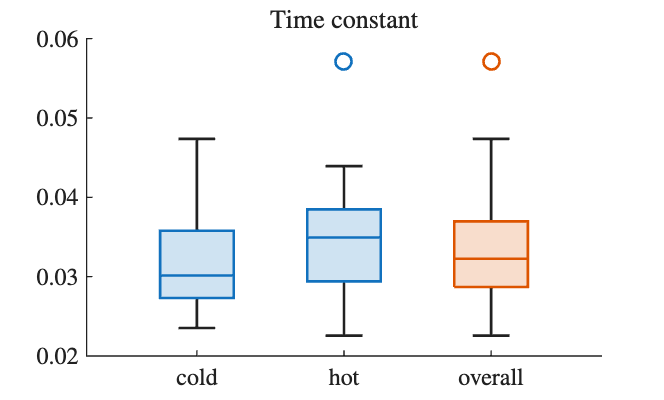


figure, clf, hold on
boxchart([[Tp_c_up Tp_c_down]', [Tp_h_up Tp_h_down]'])
boxchart([NaN(length([Tp_all_up Tp_all_down]),1) NaN(length([Tp_all_up Tp_all_down]),1) [Tp_all_up Tp_all_down]'])
xticklabels({'cold','hot','overall'})
title('Time constant')
hold off

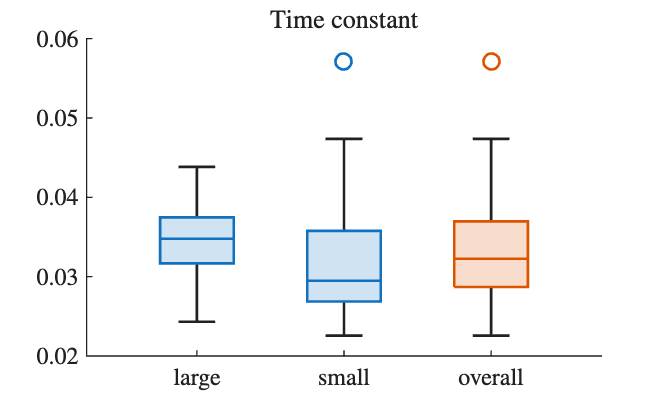


figure, clf, hold on
boxchart([[Tp_large NaN(1,length(Tp_small)-length(Tp_large))]', Tp_small'])
boxchart([NaN(length([Tp_all_up Tp_all_down]),1) NaN(length([Tp_all_up Tp_all_down]),1) [Tp_all_up Tp_all_down]'])
xticklabels({'large','small','overall'})
title('Time constant')
hold off


Td_c_up = [Td_c_1([1,3,5,7]) Td_c_2([1,3,5,7]) Td_c_3([1,3,5]) Td_c_4([1,3,5])];
Td_h_up = [Td_h_1([1,3,5,7]) Td_h_2([1,3,5,7]) Td_h_3([1,3,5]) Td_h_4([1,3,5])];
Td_c_down = [Td_c_1([2 4 6 8]) Td_c_2([2 4 6 8]) Td_c_3([2 4 6]) Td_c_4([2 4 6])];
Td_h_down = [Td_h_1([2 4 6 8]) Td_h_2([2 4 6 8]) Td_h_3([2 4 6]) Td_h_4([2 4 6])];

Td_all_up = [Td_c_1([1,3,5,7]) Td_c_2([1,3,5,7]) Td_c_3([1,3,5]) Td_c_4([1,3,5]) Td_h_1([1,3,5,7]) Td_h_2([1,3,5,7]) Td_h_3([1,3,5]) Td_h_4([1,3,5])];
Td_all_down = [Td_c_1([2 4 6 8]) Td_c_2([2 4 6 8]) Td_c_3([2 4 6]) Td_c_4([2 4 6]) Td_h_1([2 4 6 8]) Td_h_2([2 4 6 8]) Td_h_3([2 4 6]) Td_h_4([2 4 6])];

Td_small = [Td_c_1 Td_c_2 Td_h_1 Td_h_2]

Td_small =     0.0445    0.0302    0.0306    0.0343    0.0434    0.0197    0.0344    0.0205    0.0447    0.0442    0.0293    0.0468    0.0429    0.0313    0.0351    0.0300    0.0316    0.0338    0.0291    0.0360    0.0288    0.0198    0.0234    0.0187    0.0306    0.0287    0.0238    0.0348    0.0433    0.0310    0.0302    0.0172


Td_large = [Td_c_3 Td_c_4 Td_h_3 Td_h_4]

Td_large =     0.0555    0.0299    0.0435    0.0342    0.0441    0.0336    0.0481    0.0318    0.0438    0.0347    0.0464    0.0347    0.0548    0.0340    0.0454    0.0348    0.0459    0.0350    0.0455    0.0092    0.0305    0.0309    0.0351    0.0236



Td_all = [Td_all_up Td_all_down]

Td_all =     0.0445    0.0306    0.0434    0.0344    0.0447    0.0293    0.0429    0.0351    0.0555    0.0435    0.0441    0.0481    0.0438    0.0464    0.0316    0.0291    0.0288    0.0234    0.0306    0.0238    0.0433    0.0302    0.0548    0.0454    0.0459    0.0455    0.0305    0.0351    0.0302    0.0343    0.0197    0.0205    0.0442    0.0468    0.0313    0.0300    0.0299    0.0342    0.0336    0.0318    0.0347    0.0347    0.0338    0.0360    0.0198    0.0187    0.0287    0.0348    0.0310    0.0172


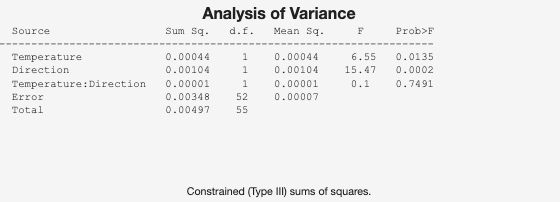


% Then continue with the ANOVA code
y = [Td_c_up, Td_h_up, Td_c_down, Td_h_down];

n = length(Td_c_up);

temperature = [ones(n,1); 2*ones(n,1); ones(n,1); 2*ones(n,1)];
direction = [ones(n,1); ones(n,1); 2*ones(n,1); 2*ones(n,1)];

[p, tbl, stats] = anovan(y, {temperature, direction}, ...
    'model', 'interaction', ...
    'varnames', {'Temperature', 'Direction'});


disp(tbl);

    {'Source'               }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'Temperature'          }    {[4.3876e-04]}    {[   1]}    {[        0]}    {[4.3876e-04]}    {[  6.5473]}    {[    0.0135]}
    {'Direction'            }    {[    0.0010]}    {[   1]}    {[        0]}    {[    0.0010]}    {[ 15.4672]}    {[2.4976e-04]}
    {'Temperature:Direction'}    {[6.9302e-06]}    {[   1]}    {[        0]}    {[6.9302e-06]}    {[  0.1034]}    {[    0.7491]}
    {'Error'                }    {[    0.0035]}    {[  52]}    {[        0]}    {[6.7014e-05]}    {0×0 double}    {0×0 double  }
    {'Total'                }    {[    0.0050]}    {[  55]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



p

p =     0.0135
    0.0002
    0.7491


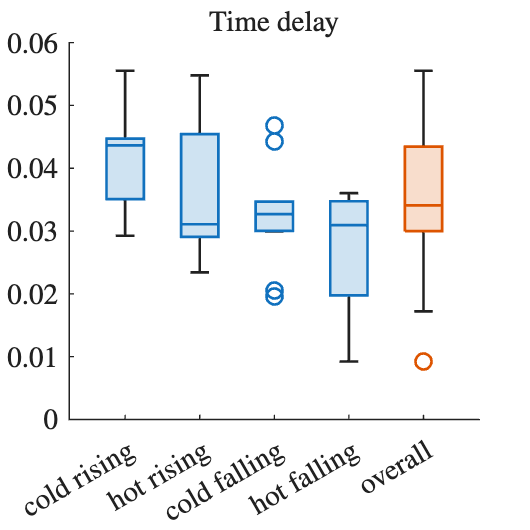


% If interaction is significant, run post-hoc comparisons
if p(3) < 0.05
    figure;
    multcompare(stats, 'Dimension', [1 2]);
end

figure, clf, hold on
boxchart([Td_c_up',Td_h_up',Td_c_down',Td_h_down'])
boxchart([NaN(length([Td_all_up Td_all_down]),1) NaN(length([Td_all_up Td_all_down]),1) NaN(length([Td_all_up Td_all_down]),1) NaN(length([Td_all_up Td_all_down]),1) [Td_all_up Td_all_down]'])
xticklabels({'cold rising', 'hot rising','cold falling','hot falling', 'overall'})
title('Time delay')
set(findall(gca, 'Type', 'Line'), 'LineWidth', 1.5);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

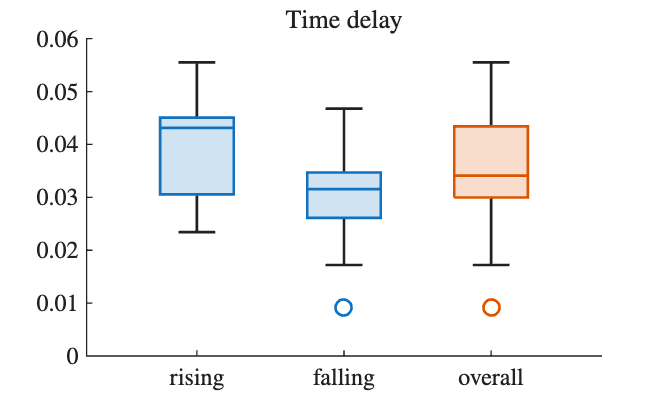


figure, clf, hold on
boxchart([[Td_c_up Td_h_up]', [Td_c_down Td_h_down]'])
boxchart([NaN(length([Td_all_up Td_all_down]),1) NaN(length([Td_all_up Td_all_down]),1) [Td_all_up Td_all_down]'])
xticklabels({'rising','falling','overall'})
title('Time delay')
hold off

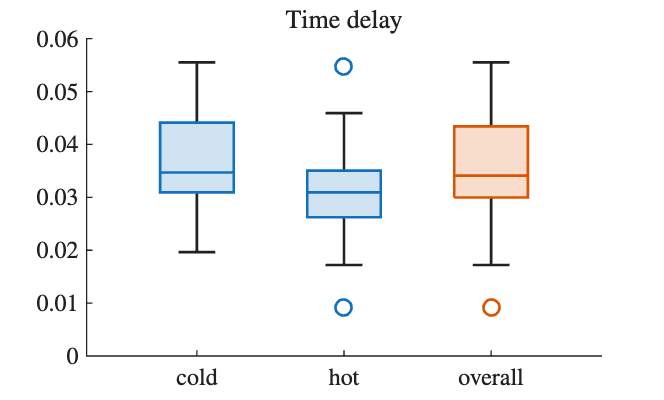


figure, clf, hold on
boxchart([[Td_c_up Td_c_down]', [Td_h_up Td_h_down]'])
boxchart([NaN(length([Td_all_up Td_all_down]),1) NaN(length([Td_all_up Td_all_down]),1) [Td_all_up Td_all_down]'])
xticklabels({'cold','hot','overall'})
title('Time delay')
hold off

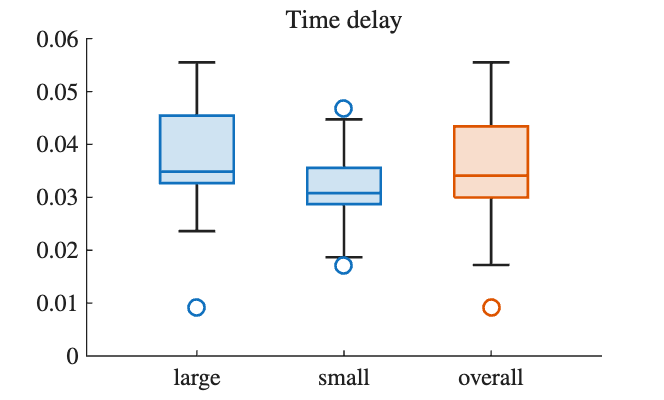


figure, clf, hold on
boxchart([[Td_large NaN(1,length(Td_small)-length(Td_large))]', Td_small'])
boxchart([NaN(length([Td_all_up Td_all_down]),1) NaN(length([Td_all_up Td_all_down]),1) [Td_all_up Td_all_down]'])
xticklabels({'large','small','overall'})
title('Time delay')
hold off


Kp_1_2_throttle = [30 30 50 50 70 70 90 90];
Kp_3_4_throttle = [25 25 55 55 85 85];

y = fit([Kp_1_2_throttle Kp_1_2_throttle Kp_1_2_throttle Kp_1_2_throttle Kp_3_4_throttle Kp_3_4_throttle Kp_3_4_throttle Kp_3_4_throttle]',[Kp_c_1 Kp_c_2 Kp_h_1 Kp_h_2 Kp_c_3 Kp_c_4 Kp_h_3 Kp_h_4]','poly1')

y =      Linear model Poly1:
     y(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       0.102  (0.09325, 0.1107)
       p2 =       3.333  (2.787, 3.879)

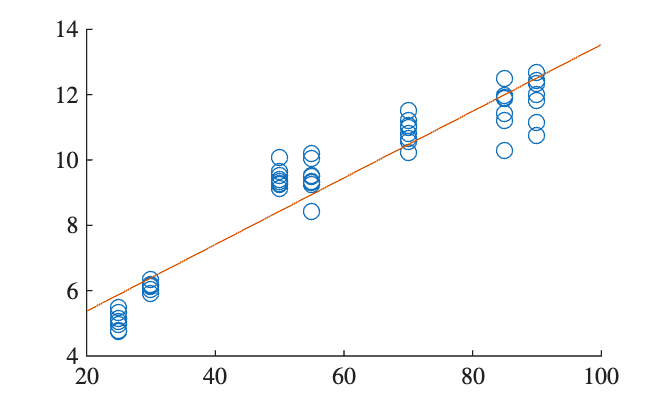


figure, clf, hold on
scatter([Kp_1_2_throttle Kp_1_2_throttle Kp_1_2_throttle Kp_1_2_throttle Kp_3_4_throttle Kp_3_4_throttle Kp_3_4_throttle Kp_3_4_throttle],[Kp_c_1 Kp_c_2 Kp_h_1 Kp_h_2 Kp_c_3 Kp_c_4 Kp_h_3 Kp_h_4])
plot((20:100),y(20:100))
hold off


Tp_mean = mean(rmoutliers(Tp_all)) %[Tp_c_1 Tp_c_2 Tp_c_3 Tp_c_4 Tp_h_1 Tp_h_2 Tp_h_3 Tp_h_4])

Tp_mean = 0.0330

Tp_dev = std(rmoutliers(Tp_all)) %[Tp_c_1 Tp_c_2 Tp_c_3 Tp_c_4 Tp_h_1 Tp_h_2 Tp_h_3 Tp_h_4])*100/Tp_mean

Tp_dev = 0.0059

Tp_dev_p = std(rmoutliers(Tp_all))*100/Tp_mean

Tp_dev_p = 18.0302


Td_mean = mean(rmoutliers(Td_all)) %[Td_c_1 Td_c_2 Td_c_3 Td_c_4 Td_h_1 Td_h_2 Td_h_3 Td_h_4])

Td_mean = 0.0349

Td_dev = std(rmoutliers(Td_all)) %[Td_c_1 Td_c_2 Td_c_3 Td_c_4 Td_h_1 Td_h_2 Td_h_3 Td_h_4])*100/Td_mean 

Td_dev = 0.0089

Td_dev_p = std(rmoutliers(Td_all))*100/Td_mean

Td_dev_p = 25.6493


Td_up_mean = mean(rmoutliers([Td_c_up Td_h_up]))

Td_up_mean = 0.0387

Td_up_dev = std(rmoutliers([Td_c_up Td_h_up]))*100/Td_up_mean

Td_up_dev = 23.0069

Td_down_mean = mean(rmoutliers([Td_c_down Td_h_down]))

Td_down_mean = 0.0308

Td_down_dev = std(rmoutliers([Td_c_down Td_h_down]))*100/Td_down_mean

Td_down_dev = 19.8316

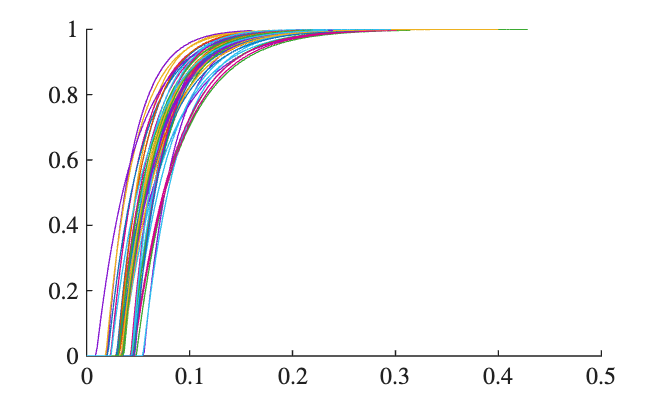


s = tf("s");
figure, clf, hold on
for i=1:8
    [y,t] = step((1/(Tp_c_1(i)*s + 1))*(exp(-Td_c_1(i)*s)));
    plot(t,y)
    [y,t] = step((1/(Tp_c_2(i)*s + 1))*(exp(-Td_c_2(i)*s)));
    plot(t,y)
    [y,t] = step((1/(Tp_h_1(i)*s + 1))*(exp(-Td_h_1(i)*s)));
    plot(t,y)
    [y,t] = step((1/(Tp_h_2(i)*s + 1))*(exp(-Td_h_2(i)*s)));
    
end
for i=1:6
    [y,t] = step((1/(Tp_c_3(i)*s + 1))*(exp(-Td_c_3(i)*s)));
    plot(t,y)
    [y,t] = step((1/(Tp_c_4(i)*s + 1))*(exp(-Td_c_4(i)*s)));
    plot(t,y)
    [y,t] = step((1/(Tp_h_3(i)*s + 1))*(exp(-Td_h_3(i)*s)));
    plot(t,y)
    [y,t] = step((1/(Tp_h_4(i)*s + 1))*(exp(-Td_h_4(i)*s)));
    plot(t,y)

end
hold off